b747_state_space;
[V D] = eigs(A_lon)

V =    0.0211 + 0.0166i   0.0211 - 0.0166i  -0.9983 + 0.0000i  -0.9983 + 0.0000i
   0.9996 + 0.0000i   0.9996 + 0.0000i  -0.0573 + 0.0097i  -0.0573 - 0.0097i
  -0.0001 + 0.0011i  -0.0001 - 0.0011i  -0.0001 - 0.0000i  -0.0001 + 0.0000i
   0.0011 - 0.0004i   0.0011 + 0.0004i   0.0001 + 0.0021i   0.0001 - 0.0021i


D =   -0.3719 + 0.8875i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.3719 - 0.8875i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0033 + 0.0672i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0033 - 0.0672i


x0_sp = real(V(:,1));
x0_ph = real(V(:,3));
x0 = (x0_ph + x0_sp)/2

x0 =    -0.4886
    0.4712
   -0.0001
    0.0006


### Longitudinal

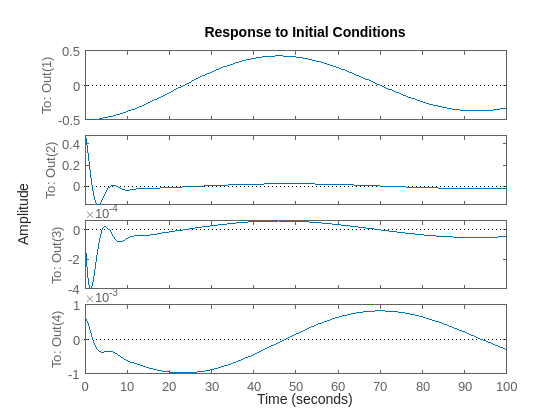

initial(ss(A_lon, B_lon(:,1), eye(4), []), x0, 100)

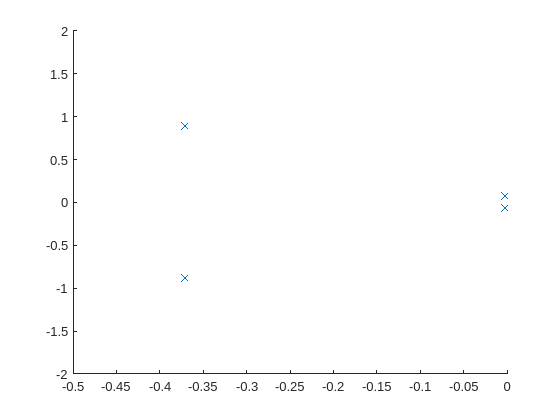

scatter(real(eig(A_lon)), imag(eig(A_lon)), 'x'); xlim([-0.5, 0]); ylim([-2, 2])

### Get rid of short period

Q_sp = diag([0 1 0 0])

Q_sp =      0     0     0     0
     0     1     0     0
     0     0     0     0
     0     0     0     0


R = diag([1 1])

R =      1     0
     0     1


K_sp = lqr(A_lon, B_lon, Q_sp, R)

K_sp =     0.0028   -0.9898  -23.9100   -0.0015
    0.0000   -0.0004   -0.0165   -0.0000


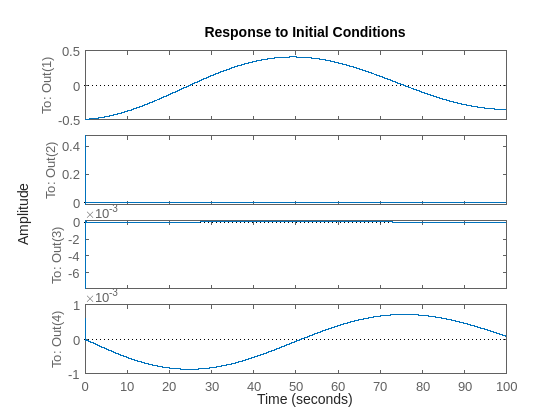

initial(ss(A_lon - B_lon*K_sp, B_lon(:,1), eye(4), []), x0, 100)

A_cl = A_lon-B_lon*K_sp;
eig(A_cl)

ans =  -23.0497 +19.3036i
 -23.0497 -19.3036i
  -0.0034 + 0.0616i
  -0.0034 - 0.0616i


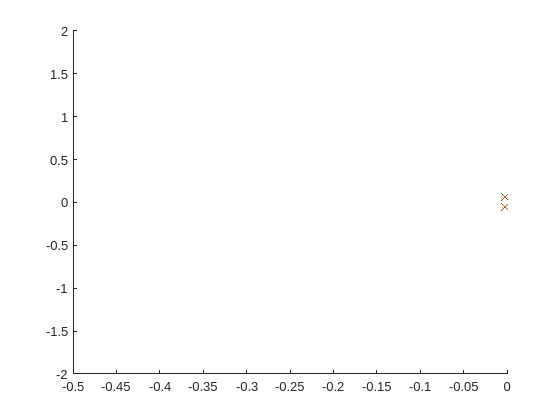

scatter(real(eig(A_cl)), imag(eig(A_cl)), 'x'); xlim([-0.5, 0]); ylim([-2, 2]); hold on;

Q_ph = diag([1 0 0 0])

Q_ph =      1     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


K_ph = lqr(A_lon, B_lon, Q_ph, R)

K_ph =     0.0201    0.0019   -1.4784   -3.3326
    0.9991    0.0014   -0.1889   -3.2632


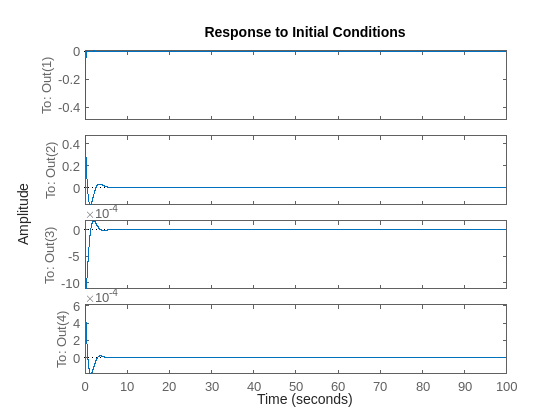

initial(ss(A_lon - B_lon*K_ph, B_lon(:,2), eye(4), []), x0, 100)

eig(A_lon-B_lon*K_ph)

ans =   -9.6634 + 0.0000i
  -1.0002 + 1.3319i
  -1.0002 - 1.3319i
  -0.4162 + 0.0000i


### Both, but less aggressive

Q_both = diag([1 1 1 1]);
R_both = diag([1000, 1000]);
K_both = lqr(A_lon, B_lon, Q_both, R_both)

K_both =     0.0051   -0.0250   -5.4819   -3.0100
    0.0299    0.0020   -0.0740   -1.9009


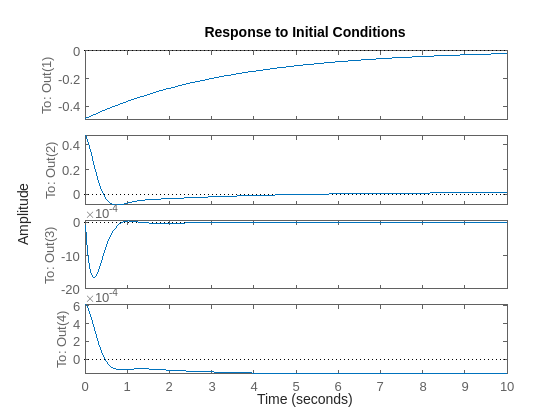

fb_sys = ss(A_lon - B_lon*K_both, B_lon, eye(4), []);
initial(fb_sys, x0, 10)

eig(A_lon - B_lon*K_both)

ans =  -12.2718 +11.6297i
 -12.2718 -11.6297i
  -3.0536 + 0.0000i
  -0.0043 + 0.0000i


## Lateral: Roll Controller

Q_roll = diag([1 1 1 10]);
R_roll = diag([10 10]);
K_roll = lqr(A_lat, B_lat, Q_roll, R_roll)

K_roll =    -0.0019   -1.9209   -0.2865   -1.1005
    0.3124   -0.0898  -27.8783    1.0731


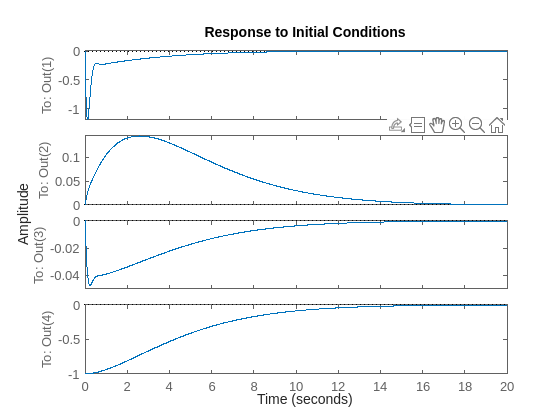

fb_sys = ss(A_lat - B_lat*K_roll, B_lat, eye(4), []);
x0_roll = [0; 0; 0; -1];
initial(fb_sys, x0_roll, 20);